## Motorized Bar Mechanism  

We created a rigid linkage mechanism with 4 bars and a slider cranck. L20 is a 0.2 m long link with a radius of 0.03 m. Links L50 and L70 are longer variations of the same link.

All links have a revolute joint attached at the base and the linkage has 2 closed-loop joints. A revolute joint closes the top loop (4 bar mechanism) while a prismatic joint forms the slider in the lower loop (slider-crank mechanism). The revolute joint attached to  `L20 `is actuated and controlled by input angles.

SorosimLinks (`L20, L50 and L70`) and SorosimLinkage (M) are saved in Four`Bar_SliderCrank.mat`

load('FourBar_SliderCrank.mat')

To see the properties of `L20`

L20

L20 =   SorosimLink with properties:

    jointtype: 'R'
     linktype: 'r'
         npie: 1
           ld: []
            L: 0.2000
           CS: 'C'
            r: @(X1)0.03
            h: []
            w: []
            a: []
            b: []
           cx: 0.1000
           gi: [4×4 double]
           gf: [4×4 double]
            E: []
          Poi: []
            G: []
          Eta: []
          Rho: 1000
           Kj: 0
           Dj: 0
            M: [6×6 double]
          n_l: 25
          n_r: 18
        color: [0.0462 0.0971 0.8235]
        alpha: 1
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.0827

To see the properties of L50

L50

L50 =   SorosimLink with properties:

    jointtype: 'R'
     linktype: 'r'
           CS: 'C'
         npie: 1
           lp: []
            L: 0.5000
            r: @(X1)0.03
            h: []
            w: []
            a: []
            b: []
           gi: [4×4 double]
           gf: [4×4 double]
            E: []
          Poi: []
            G: []
          Eta: []
          Rho: 1000
           Kj: 0
           Dj: 0
            M: [6×6 double]
          n_l: 25
          n_r: 18
        color: [0.6948 0.3171 0.9502]
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.1122


To see the properties of L70

L70

L70 =   SorosimLink with properties:

    jointtype: 'R'
     linktype: 'r'
           CS: 'C'
         npie: 1
           lp: []
            L: 0.7000
            r: @(X1)0.03
            h: []
            w: []
            a: []
            b: []
           gi: [4×4 double]
           gf: [4×4 double]
            E: []
          Poi: []
            G: []
          Eta: []
          Rho: 1000
           Kj: 0
           Dj: 0
            M: [6×6 double]
          n_l: 25
          n_r: 18
        color: [0.0344 0.4387 0.3816]
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.1256


To see the properties of M

M

M =   SorosimLinkage with properties:

                      N: 5
                   ndof: 5
                   nsig: 10
                     nj: 5
                 VLinks: [1×3 SorosimLink]
              LinkIndex: [5×1 double]
                 CVRods: {5×1 cell}
                  iLpre: [5×1 double]
                  g_ini: [20×4 double]
                Z_order: 4
               OneBasis: 0
                   nCLj: 2
                   iCLA: [2×1 double]
                   iCLB: [0 0]
               VRodsCLj: [1×2 SorosimRod]
                  gACLj: {2×1 cell}
                  gBCLj: {2×1 cell}
           CLprecompute: [1×1 struct]
                   T_BS: 0.0100
                Gravity: 0
                      G: [6×1 double]
                     np: 0
            LocalWrench: [1×0 double]
                 Fp_loc: {0×1 cell}
                 Fp_vec: {0×1 cell}
                 Fp_sig: [0×1 double]
          

To see the problem definition:

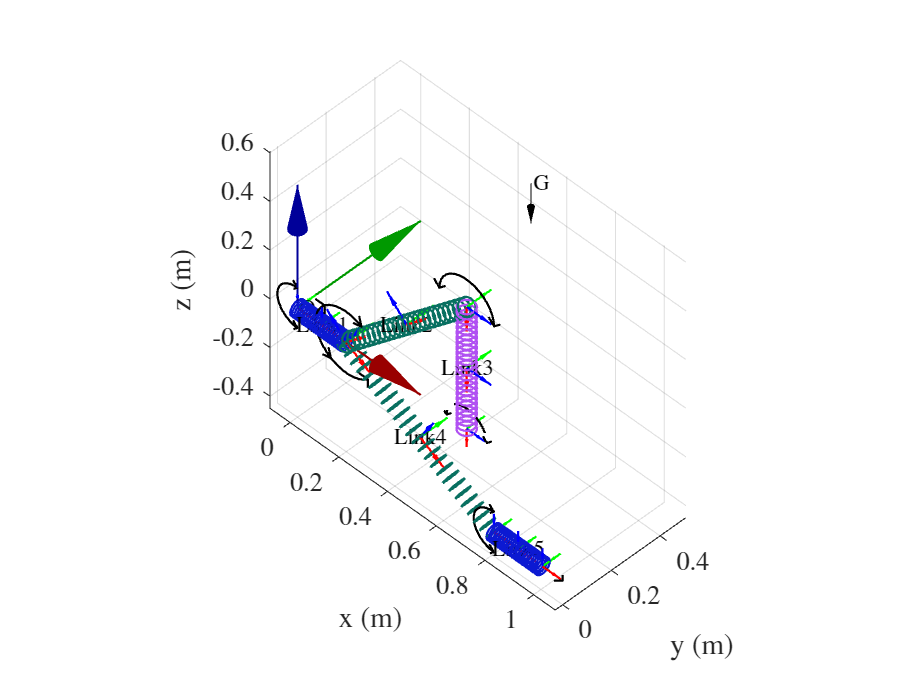

M.plotq0

The result should be:

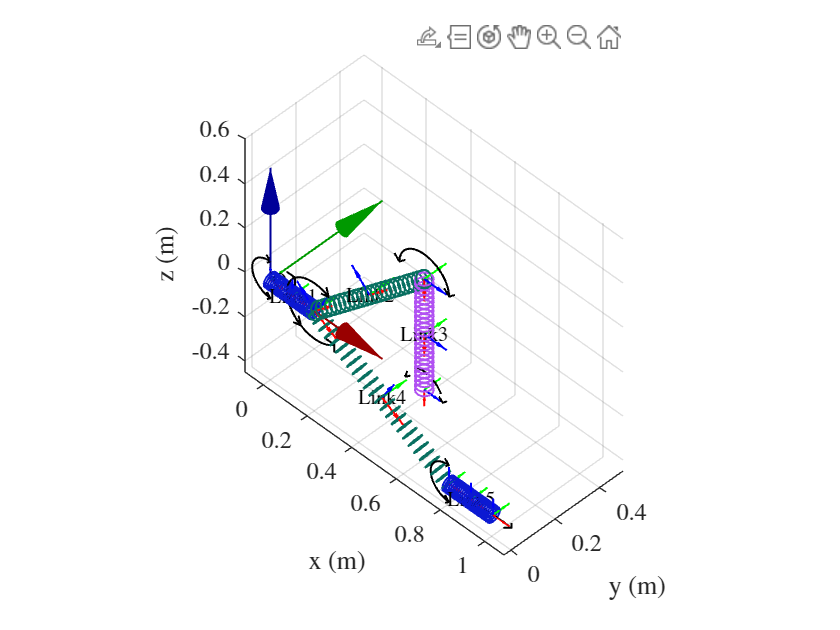

The revolute joint of link 1 is actuated by the value of the joint angle.

### **Dynamic Analysis**

For dynamics problem, type:

[t,qqd]=M.dynamics;

Index exceeds the number of array elements. Index must not exceed 0.
Error in SorosimLinkage/dynamics (line 85)
    q0   = eval(['[',answer{1},']'])';

The user can enter the angle of the actuated revolute joint as a function of time to simulate the motion of the mechanism in time (eg: pi*t) . Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.